# TNA010: Computer assignments 2

### Namn: Lovisa Svensson

### Datum: 2023-12-04

## Problem 1

**Code a):**

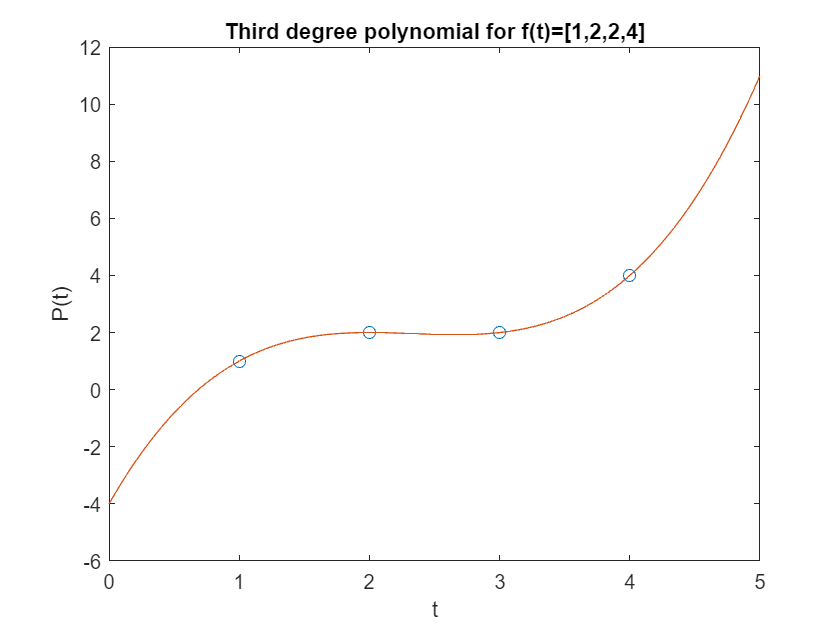

clear
clf

t = [1; 2; 3; 4];
f = [1; 2; 2; 4];
A = zeros(4, 4);

% The A matrix contains the values of f according to a third degree polynomial
for t_data = 1:4
    A(t_data, :) = [1, t_data, t_data^2, t_data^3]; % 1 + t + t^2 + t^3
end

% QR decomposition to find x
[Q,R] = qr(A);
x = R \ (Q' * f);

% Third degree polynomial
P = @(t) x(1) + x(2)*t + x(3)*t.^2 + x(4)*t.^3;

% Plotting t and function values
t_values = linspace(0, 5, 100);
P_values = P(t_values);

plot(t, f, 'o'); % Actual data values
hold on
plot(t_values, P_values); % Calculated polynomial plot
title('Third degree polynomial for f(t)=[1,2,2,4]')
xlabel('t')
ylabel('P(t)')

**Code b):**

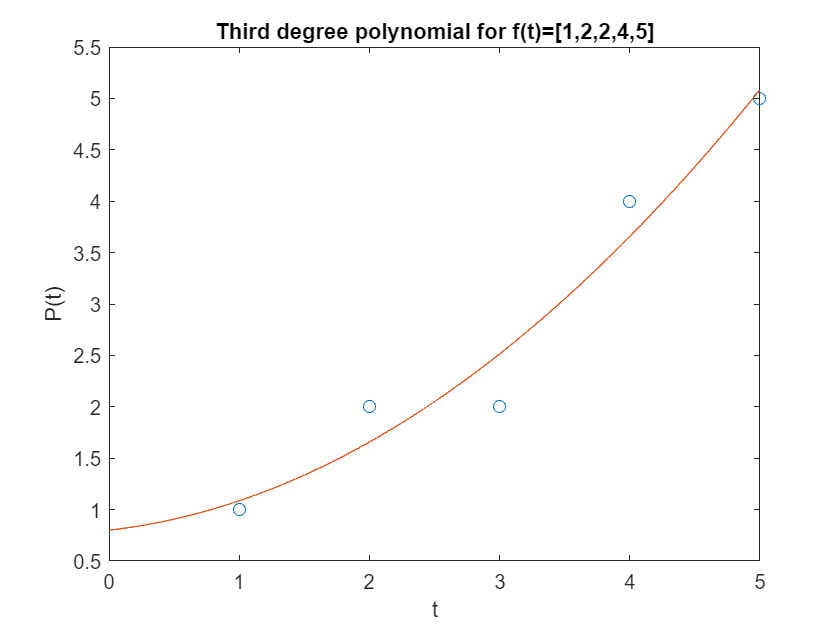

clear
clf

t = [1; 2; 3; 4; 5;];
f = [1; 2; 2; 4; 5];
A = zeros(5, 4);

% Has 5 values now
for t_data = 1:5
    A(t_data, :) = [1, t_data, t_data^2, t_data^3];
end

[Q,R] = qr(A);

x = R \ (Q' * f);

P = @(t) x(1) + x(2)*t + x(3)*t.^2 + x(4)*t.^3;

t_values = linspace(0, 5, 100);
P_values = P(t_values);

plot(t, f, 'o'); % Actual data plot
hold on
plot(t_values, P_values); % Calculated polynomial plot
title('Third degree polynomial for f(t)=[1,2,2,4,5]')
xlabel('t')
ylabel('P(t)')

The plots show that the data with 4 values gets a more accurate third-degree polynomial. The 5 data points are not very ideal for a third-degree polynomial, it is more difficult to fit a polynomial of the third degree to these 5 values than it is for 4 values. A polynomial higher than 3 degrees would likely fit the increased data better.

## Problem 3

**Code a):**

clear
clf
y = [1; 1; 1;];
evalues = zeros(10,1);
result = zeros(10,1);

for k = 0:9
    % Setup
    e = 10^(-k);
    evalues(k+1) = e;
    X = [1 1; e 0; 0 e];

    % QR
    [Q, R] = qr(X, 0);
    beta1 = R\(Q'*y);

    % NE
    C = X' * X;
    beta2 = C\(X'*y);

    result(k+1) = norm(beta1 - beta2);
end

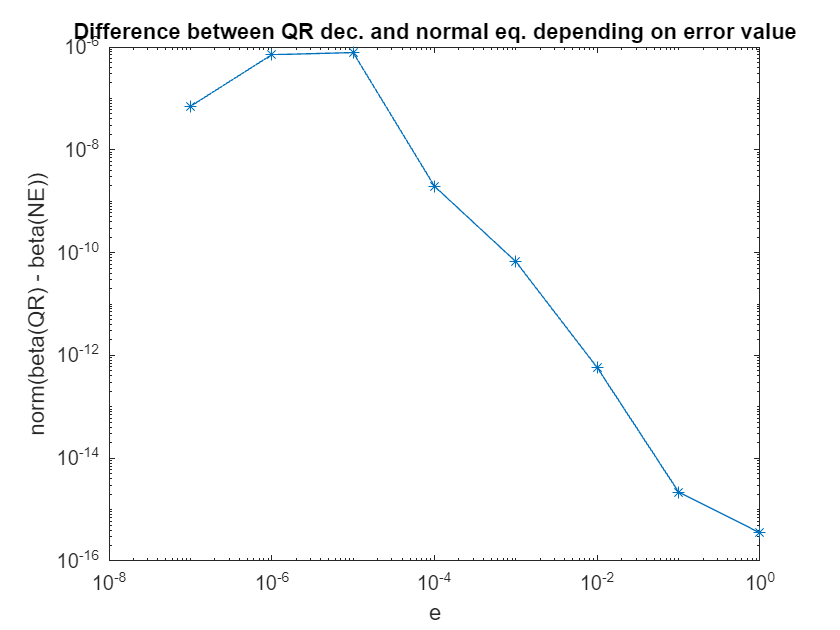

loglog(evalues, result, '-*');
title('Difference between QR dec. and normal eq. depending on error value')
xlabel('e')
ylabel('norm(beta(QR) - beta(NE))')

hold off

The graph looks a bit strange and I could not figure out why - I computed the solution by following 3.6 and 5.2 in the book. The smaller e is, the higher the difference should get, instead of going down as it does in the plot. The plot shows the difference between the methods, so the smaller e is the more the methods differ from each other. I don't know if you can tell which method is more accurate from this plot, only that one of them gets less accurate with smaller e compared to the other, however the plot in b) shows the condition numbers for the methods. The condition number for a matrix shows how "sensitive" it is to errors, so a higher condition number means that the matrix is more 'ill-conditioned' and that the correct solution becomes harder to find. In this case, the sensitivity for normal equation increases more for small e, and should be the less accurate method.

**Code b):**

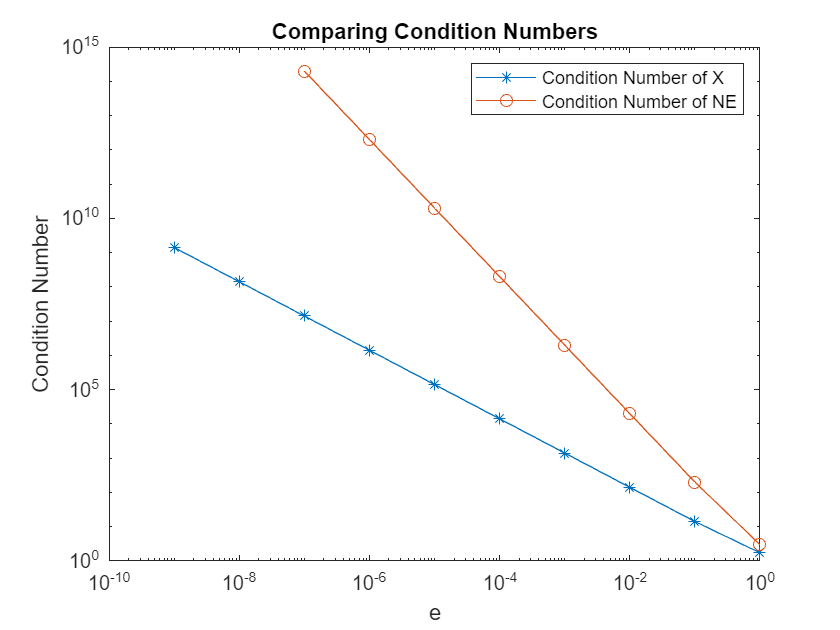

clf

evalues = zeros(16,1);
condXarray = zeros(16,1);
condNEarray = zeros(16,1);

for k = 0:9
    % Setup
    e = 10^(-k);
    evalues(k+1) = e;
    X = [1 1; e 0; 0 e];

    % Calculate condition numbers
    condX = cond(X);
    condNE = cond(X' * X);
    condXarray(k+1) = condX;
    condNEarray(k+1) = condNE;
end

% Plot the condition numbers
loglog(evalues, condXarray, '-*')
hold on
loglog(evalues, condNEarray, '-o');
title('Comparing Condition Numbers')
xlabel('e')
ylabel('Condition Number')
legend('Condition Number of X', 'Condition Number of NE')

## Problem 5

My custom QR function has a slightly larger error than MATLAB's built in function, but the errors are very small.

Code:

clear
clf

% Set the random seed for reproducibility
rng(42);

% Generate a random matrix
A = randn(5, 3);

% Use your custom myqr function
[Q_custom, R_custom] = myqr(A);

% Use MATLAB's built-in qr function
[Q_matlab, R_matlab] = qr(A);

disp(['Error for custom function: ', num2str(norm(Q_custom*R_custom - A))])

Error for custom function: 5.0428e-15


disp(['Error for MATLAB function: ', num2str(norm(Q_matlab*R_matlab - A))])

Error for MATLAB function: 5.3492e-16


function [Q,R] = myqr(A)
    [m, n] = size(A);
    Q = eye(m); % Initialize Q as an identity matrix
    
    for k = 1:min(m-1, n)
        x = A(k:m, k);
        u = househ(x);
        
        % Apply Householder transformation to A
        A(k:m, :) = apphouse(u, A(k:m, :));
        
        % Accumulate the transformation matrix Q
        Q(k:m, :) = apphouse(u, Q(k:m, :));
    end
    
    Q = Q'; % Use transposed value
    R = A; % The upper triangular matrix R is now stored in A
end

% Copied from the book
function u = househ(x)
    n = length(x);
    kap = norm(x); v = zeros(n,1);
    v(1) = x(1) + sign(x(1))*kap;
    v(2:n) = x(2:n);
    u = (1/norm(v))*v;
end

% Copied from the book
function Y = apphouse(u, X)
    Y = X - 2*u*(u'*X);
end